
% script RR_Ex10_02_passive_filters
% Solves the basic equations of four simple passive filters.
% These examples are easy to solve by hand, but illustrate how
% to put a few linear equations into A*x=b form and solve using Matlab.
% Renaissance Robotics codebase, Chapter 10, https://github.com/tbewley/RR
% Copyright 2023 by Thomas Bewley, distributed under Modified BSD License.

clear, close all, syms s Vi Vs C L R R1 R2 

% First-order low-pass RC filter: Solve for Vo as a function of Vi
% x={Ic, Ir, Vo}  <-- unknown vector   
A  =[ 1  -1   0;     % Ic - Ir = 0
      1   0 -C*s;    % Ic - C*s*Vo = 0
      0   R   1];    % R*Ir + Vo = Vi
b  =[ 0;  0; Vi];
x=A\b; Vo_LPF1=simplify(x(3))

$$Vo\_LPF1 = \frac{\mathrm{Vi}}{C\,R\,s+1}$$

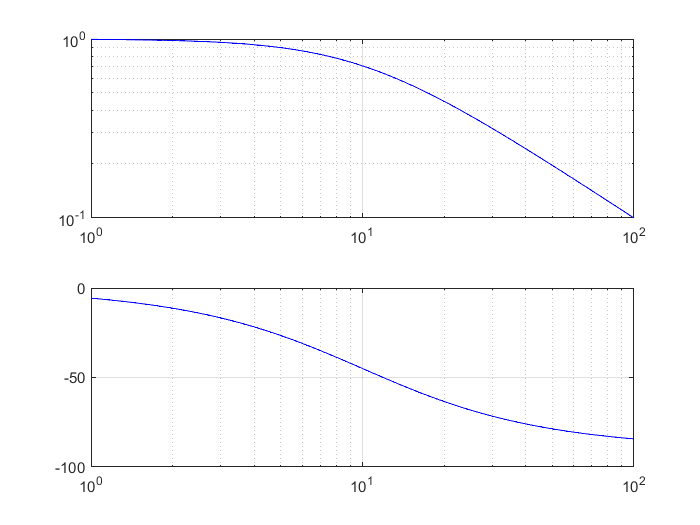

omega1=10; F_LPF1=RR_tf([omega1],[1 omega1]);
figure(1), RR_bode(F_LPF1), pause


% First-order high-pass RC filter: Solve for Vo as a function of Vi
% x={Ic, Ir, Vo}  <-- unknown vector  
A  =[ 1  -1   0;     % Ic - Ir = 0
      1   0  C*s;    % Ic + C*s*Vo = C*s*Vi
      0   R  -1];    % R*Ir - Vo = 0
b  =[ 0; C*s*Vi; 0];
x=A\b 

$$x = \left(\begin{array}{c} \frac{C\,\mathrm{Vi}\,s}{C\,R\,s+1}\\ \frac{C\,\mathrm{Vi}\,s}{C\,R\,s+1}\\ \frac{C\,R\,\mathrm{Vi}\,s}{C\,R\,s+1} \end{array}\right)$$

Vo_HPF1=simplify(x(3))

$$Vo\_HPF1 = \frac{C\,R\,\mathrm{Vi}\,s}{C\,R\,s+1}$$

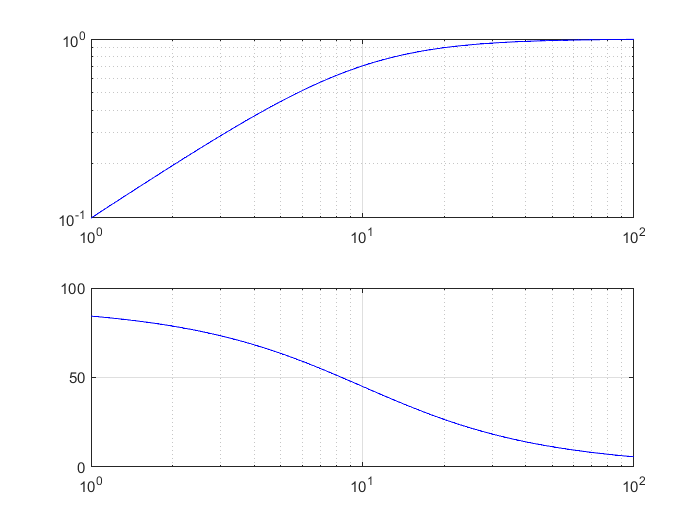

omega1=10; F_HPF1=RR_tf([1 0],[1 omega1]);
figure(2), RR_bode(F_HPF1), pause


% Voltage-biased first-order high-pass RC filter: Solve for Vo as a function of Vi and Vs
% x={I_0,I1, I2, Vo}  <-- unknown vector
A  =[ 1   1  -1   0;   % Ic + I1 - I2 = 0
      1   0   0  C*s;  % Ic + C*s*Vo = C*s*Vi
      0  R1   0   1;   % R1*I1 + Vo = Vs
      0   0  R2  -1];  % R2*I2 - Vo = 0
b  =[ 0; C*s*Vi; Vs; 0];
x=A\b 

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{C\,s\,\left(R_{1}\,\mathrm{Vi}+R_{2}\,\mathrm{Vi}-R_{2}\,\mathrm{Vs}\right)}{\sigma_{1}}\\ \frac{\mathrm{Vs}-C\,R_{2}\,\mathrm{Vi}\,s+C\,R_{2}\,\mathrm{Vs}\,s}{\sigma_{1}}\\ \frac{\mathrm{Vs}+C\,R_{1}\,\mathrm{Vi}\,s}{\sigma_{1}}\\ \frac{R_{2}\,\left(\mathrm{Vs}+C\,R_{1}\,\mathrm{Vi}\,s\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{1}+R_{2}+C\,R_{1}\,R_{2}\,s \end{array}$$

Vo_HPF1biased=simplify(x(4)), pause

$$Vo\_HPF1biased = \frac{R_{2}\,\left(\mathrm{Vs}+C\,R_{1}\,\mathrm{Vi}\,s\right)}{R_{1}+R_{2}+C\,R_{1}\,R_{2}\,s}$$


% Second-order low-pass LC filter: Solve for Vo as a function of Vi
% x={I_L,Ic,Vo}  <-- unknown vector
A  =[ 1  -1   0;    % I_L - Ic = 0
     L*s  0   1;    % L*s*I_L + Vo = Vi
      0  -1  C*s];  % C*s*Vo - Ic = 0
b  =[ 0; Vi; 0];
x=A\b 

$$x = \left(\begin{array}{c} \frac{C\,\mathrm{Vi}\,s}{C\,L\,s^{2}+1}\\ \frac{C\,\mathrm{Vi}\,s}{C\,L\,s^{2}+1}\\ \frac{\mathrm{Vi}}{C\,L\,s^{2}+1} \end{array}\right)$$

 Vo_LPF2_undamped=simplify(x(3))

$$Vo\_LPF2\_undamped = \frac{\mathrm{Vi}}{C\,L\,s^{2}+1}$$

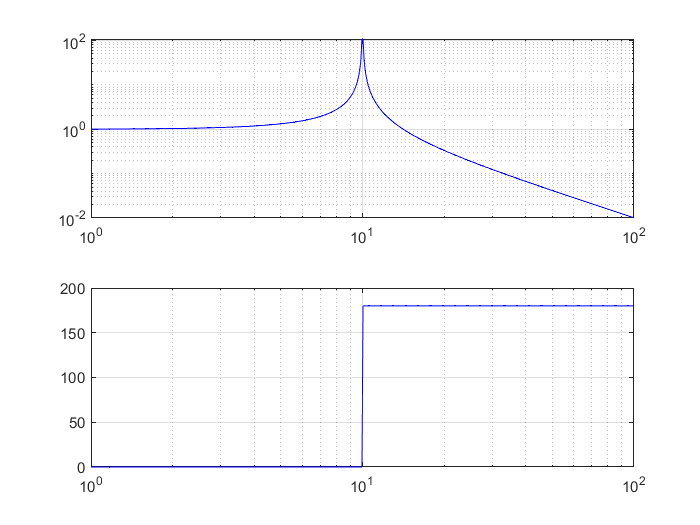

omega3=10; F_LPF2_undamped=RR_tf([omega3^2],[1 0 omega3^2]);
figure(3), RR_bode(F_LPF2_undamped)

%Question 1
clear, close all, syms s Vi Vs C L R R1 R2 R_load
% First-order low-pass RC filter: Solve for Vo as a function of Vi
% x={Ic, Ir, Vo}  <-- unknown vector
A  =[ 1 -1 -1 0 ;     % I_L-I_C-I_load = 0
      -L*s 0 0 -1;    % -V0-LsI_L=V_i
       0  1 0  -C*s;   % I_C-CsV0=0
      0 0   -R_load 1];    % V0-I_Rload*R_load=0
b  =[ 0; Vi; 0; 0];
x=A\b

$$x = \left(\begin{array}{c} -\frac{\mathrm{Vi}+C\,R_{\mathrm{load}}\,\mathrm{Vi}\,s}{C\,L\,R_{\mathrm{load}}\,s^{2}+L\,s+R_{\mathrm{load}}}\\ -\frac{C\,R_{\mathrm{load}}\,\mathrm{Vi}\,s}{C\,L\,R_{\mathrm{load}}\,s^{2}+L\,s+R_{\mathrm{load}}}\\ -\frac{\mathrm{Vi}}{C\,L\,R_{\mathrm{load}}\,s^{2}+L\,s+R_{\mathrm{load}}}\\ -\frac{R_{\mathrm{load}}\,\mathrm{Vi}}{C\,L\,R_{\mathrm{load}}\,s^{2}+L\,s+R_{\mathrm{load}}} \end{array}\right)$$

Vo_LPF3=simplify(x(4))

$$Vo\_LPF3 = -\frac{R_{\mathrm{load}}\,\mathrm{Vi}}{C\,L\,R_{\mathrm{load}}\,s^{2}+L\,s+R_{\mathrm{load}}}$$

omega4=10; F_LPF3=RR_tf([omega4^2],[1 0 omega4^2]);
figure(4), RR_bode(F_LPF3), pause